# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## This tutorial

Create fake data for a hypothetical extracellular electrophysiology experiment with a freely moving animal. The types of data we will convert are:

- Subject (species, strain, age, .etc) 

- Animal position

- Trials

- LFP

- Spike times

## Installing matnwb

Use the code below within the brackets to install MatNWB from source. MatNWB works by automatically creating API classes based on the schema. Use `generateCore()` to generate these classes.

%{
!git clone https://github.com/NeurodataWithoutBorders/matnwb.git
cd matnwb
addpath(genpath(pwd));
generateCore();
%}

## Set up the NWB file

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new `NWBFile` object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3), ...
    'general_experimenter', 'My Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', 'DOI:10.1016/j.neuron.2016.12.011'); % optional
nwb

nwb =   NwbFile with properties:

                                nwb_version: '2.2.5'
                                acquisition: [0×1 types.untyped.Set]
                                   analysis: [0×1 types.untyped.Set]
                           file_create_date: []
                                    general: [0×1 types.untyped.Set]
                    general_data_collection: []
                            general_devices: [0×1 types.untyped.Set]
             general_experiment_description: []
                       general_experimenter: 'My Name'
                general_extracellular_ephys: [0×1 types.untyped.Set]
     general_extracellular_ephys_electrodes: []
                        general_institution: 'University of My Institution'
                general_intracellular_ephys: [0×1 types.untyped.Set]
      general_intracellular_ephys_filtering: []
    general_intracellular_ephys_sweep_table: []
                

## Subject information

Create a `Subject` object to store information about the experimental subject, such as age, species, genotype, sex, and a freeform description. Then set `nwb.general_subject` to the `Subject` object.

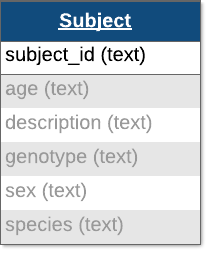

Each of these fields is free-form, so any values will be valid, but here are our recommendations:

- For `age`, we recommend using the [ISO 8601 Duration format](https://en.wikipedia.org/wiki/ISO_8601#Durations)

- For `species`, we recommend using the formal latin binomal name (e.g. mouse -> *Mus musculus*, human -> *Homo sapiens*)

- For `sex`, we recommend using F (female), M (male), U (unknown), and O (other)

subject = types.core.Subject( ...
    'subject_id', '001', ...
    'age', 'P90D', ...
    'description', 'mouse 5', ...
    'species', 'Mus musculus', ...
    'sex', 'M')

subject =   Subject with properties:

              age: 'P90D'
    date_of_birth: []
      description: 'mouse 5'
         genotype: []
              sex: 'M'
          species: 'Mus musculus'
       subject_id: '001'
           weight: []


nwb.general_subject = subject;

## SpatialSeries and Position

Many types of data have special data types in NWB. To store the spatial position of a subject, we will use the `SpatialSeries` and `Position` classes. 

`SpatialSeries` is a subclass of `TimeSeries`. `TimeSeries` is a common base class for measurements sampled over time, and provides fields for data and time (regularly or irregularly sampled).

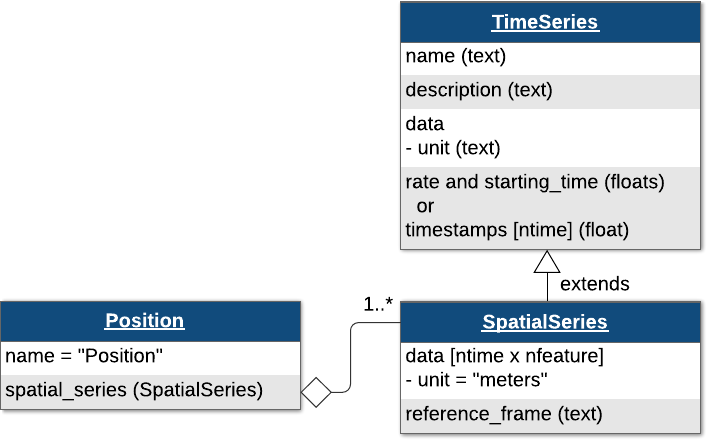 

Here, we put a `SpatialSeries` object called `'SpatialSeries'` in a `Position` object, and put that in a  `ProcessingModule` named `'behavior'`.

position_data = [linspace(0,10,100); linspace(0,8,100)];

spatial_series_ts = types.core.SpatialSeries( ...
    'data', position_data, ...
    'reference_frame', '(0,0) is bottom left corner', ...
    'timestamps', linspace(0, 100)/200)

spatial_series_ts =   SpatialSeries with properties:

        reference_frame: '(0,0) is bottom left corner'
     starting_time_unit: 'seconds'
    timestamps_interval: 1
        timestamps_unit: 'seconds'
               comments: 'no comments'
                control: []
    control_description: []
                   data: [2×100 double]
        data_conversion: 1
        data_resolution: -1
              data_unit: 'meters'
            description: 'no description'
          starting_time: []
     starting_time_rate: []
             timestamps: [1×100 double]


To help data analysis and visualization tools know that this `SpatialSeries` object represents the position of the animal, store the `SpatialSeries` object inside of a `Position` object.

Position = types.core.Position('SpatialSeries', spatial_series_ts);

NWB differentiates between raw, *acquired data*, which should never change, and *processed data*, which are the results of preprocessing algorithms and could change. Let's assume that the animal's position was computed from a video tracking algorithm, so it would be classified as processed data. Since processed data can be very diverse, NWB allows us to create processing modules, which are like folders, to store related processed data or data that comes from a single algorithm.

Create a processing module called "behavior" for storing behavioral data in the `NWBFile` and add the `Position` object to the module.

% create processing module
behavior_mod = types.core.ProcessingModule( ...
    'description',  'contains behavioral data')

behavior_mod =   ProcessingModule with properties:

         description: 'contains behavioral data'
        dynamictable: [0×1 types.untyped.Set]
    nwbdatainterface: [0×1 types.untyped.Set]



% add the Position object (that holds the SpatialSeries object)
behavior_mod.nwbdatainterface.set(...
    'Position', Position);

% add the processing module to the NWBFile object, and name it "behavior"
nwb.processing.set('behavior', behavior_mod);

## Test write

Now, write the NWB file that we have built so far.

nwbExport(nwb, 'ecephys_tutorial1.nwb')

We can then read the file and print it to inspect its contents. We can also print the `SpatialSeries` data that we created by referencing the names of the objects in the hierarchy that contain it. The processing module called `'behavior'` contains our `Position` object. By default, the `Position` object is named `'Position'`. The `Position` object contains our `SpatialSeries` object named `'SpatialSeries'`.

read_nwbfile = nwbRead('ecephys_tutorial1.nwb')

read_nwbfile =   NwbFile with properties:

                                nwb_version: '2.2.5'
                                acquisition: [0×1 types.untyped.Set]
                                   analysis: [0×1 types.untyped.Set]
                           file_create_date: [1×1 types.untyped.DataStub]
                                    general: [0×1 types.untyped.Set]
                    general_data_collection: []
                            general_devices: [0×1 types.untyped.Set]
             general_experiment_description: []
                       general_experimenter: [1×1 types.untyped.DataStub]
                general_extracellular_ephys: [0×1 types.untyped.Set]
     general_extracellular_ephys_electrodes: []
                        general_institution: 'University of My Institution'
                general_intracellular_ephys: [0×1 types.untyped.Set]
      general_intracellular_ephys_filtering: []
    genera

read_nwbfile.processing.get('behavior').nwbdatainterface.get('Position').spatialseries.get('SpatialSeries')

ans =   SpatialSeries with properties:

        reference_frame: '(0,0) is bottom left corner'
     starting_time_unit: 'seconds'
    timestamps_interval: 1
        timestamps_unit: 'seconds'
               comments: 'no comments'
                control: []
    control_description: []
                   data: [1×1 types.untyped.DataStub]
        data_conversion: 1
        data_resolution: -1
              data_unit: 'meters'
            description: 'no description'
          starting_time: []
     starting_time_rate: []
             timestamps: [1×1 types.untyped.DataStub]


We can also use the [HDFView](https://www.hdfgroup.org/downloads/hdfview/) tool to inspect the resulting NWB file.

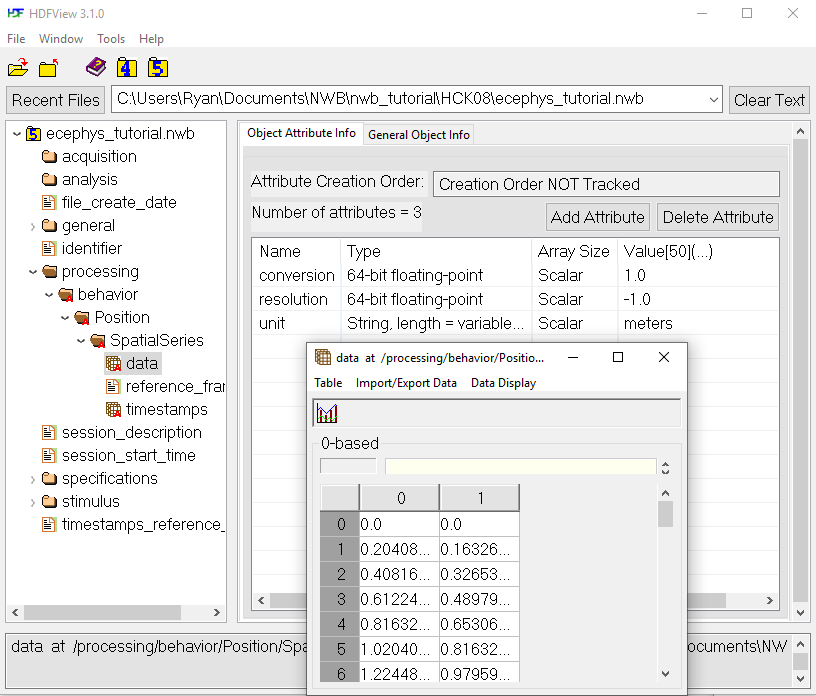

## Trials

Trials are stored in a `TimeIntervals` object which is a subclass of `DynamicTable`. `DynamicTable` objects are used to store tabular metadata throughout NWB, including for trials, electrodes, and sorted units. They offer flexibility for tabular data by allowing required columns, optional columns, and custom columns.

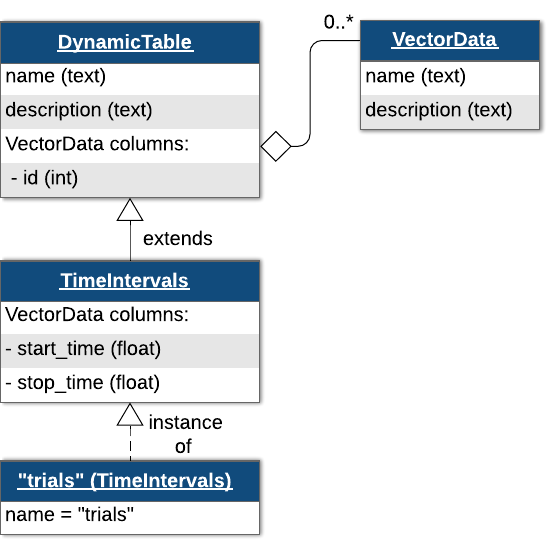

The trials `DynamicTable` can be thought of as a table with this structure:

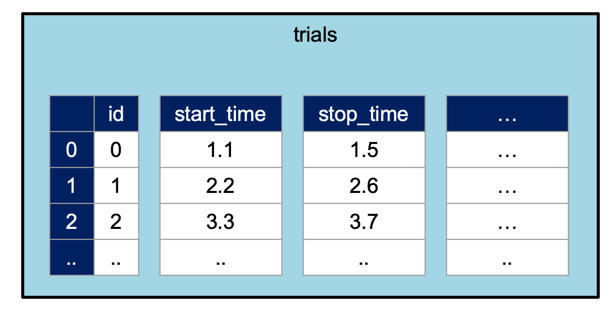

Trials are stored in a `TimeInterval` object which subclasses  DynamicTable. Here, we are adding `'correct'`, which will be a `boolean` array.

trials = types.core.TimeIntervals( ...
    'colnames', {'start_time', 'stop_time', 'correct'}, ...
    'description', 'trial data and properties', ...
    'id', types.hdmf_common.ElementIdentifiers('data', 0:2), ...
    'start_time', types.hdmf_common.VectorData('data', [.1, 1.5, 2.5], ...
   	'description','start time of trial'), ...
    'stop_time', types.hdmf_common.VectorData('data', [1., 2., 3.], ...
   	'description','end of each trial'), ...
    'correct', types.hdmf_common.VectorData('data', [false, true, false], ...
   	'description', 'whether the trial was correct'))

trials =   TimeIntervals with properties:

          start_time: [1×1 types.hdmf_common.VectorData]
           stop_time: [1×1 types.hdmf_common.VectorData]
                tags: []
          tags_index: []
          timeseries: []
    timeseries_index: []
            colnames: {'start_time'  'stop_time'  'correct'}
         description: 'trial data and properties'
                  id: [1×1 types.hdmf_common.ElementIdentifiers]
          vectordata: [1×1 types.untyped.Set]
         vectorindex: [0×1 types.untyped.Set]


nwb.intervals_trials = trials;

## Extracellular electrophysiology

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in a `electrodes` table, which is also a `DynamicTable`. `electrodes` has several required fields: x, y, z, impedence, location, filtering, and electrode_group.

## Electrode table

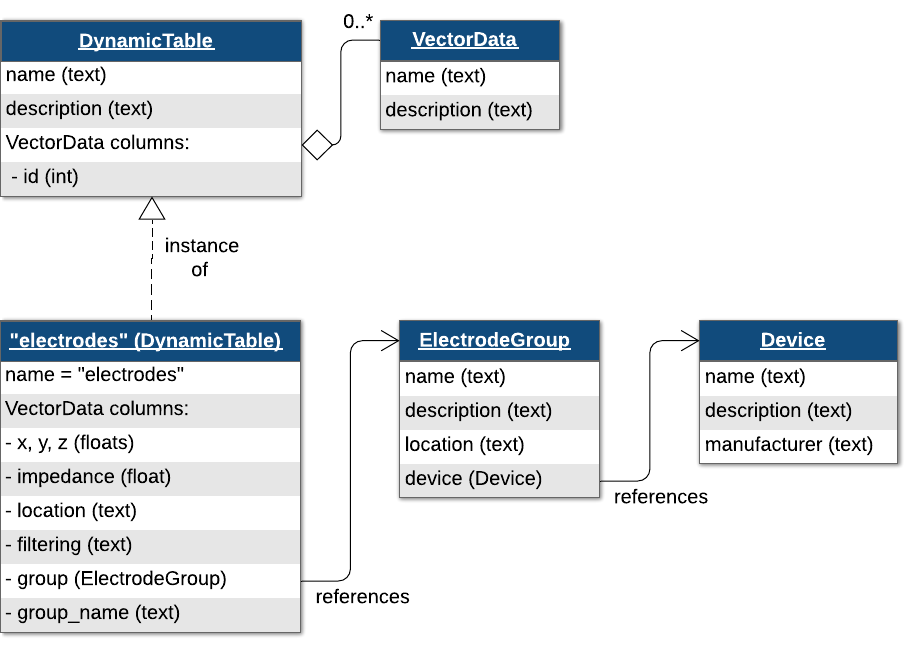

Since this is a `DynamicTable`, we can add additional metadata fields. We will be adding a "label" column to the table.

Here, we also demonstate another method for creating `DynamicTable`s, by first creating a MATLAB native `Table` object and then calling `util.table2nwb` to convert this `Table` object into a `DynamicTable`.

nshanks = 4;
nchannels_per_shank = 3;
variables = {'x', 'y', 'z', 'imp', 'location', 'filtering', 'group', 'label'};
tbl = cell2table(cell(0, length(variables)), 'VariableNames', variables);
device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000');
device_name = 'array';
nwb.general_devices.set(device_name, device);
device_link = types.untyped.SoftLink(['/general/devices/' device_name]);
for ishank = 1:nshanks
    group_name = ['shank' num2str(ishank)];
    nwb.general_extracellular_ephys.set(group_name, ...
        types.core.ElectrodeGroup( ...
            'description', ['electrode group for shank' num2str(ishank)], ...
   	        'location', 'brain area', ...
   	        'device', device_link));
    group_object_view = types.untyped.ObjectView( ...
       	['/general/extracellular_ephys/' group_name]);
    for ielec = 1:nchannels_per_shank
        tbl = [tbl; {5.3, 1.5, 8.5, NaN, 'unknown', 'unknown', ...
            group_object_view, [group_name 'elec' num2str(ielec)]}];
    end
end
tbl

tbl = 12×8 table
     x      y      z     imp    location     filtering                group                     label    
    ___    ___    ___    ___    _________    _________    ______________________________    _____________

    5.3    1.5    8.5    NaN    'unknown'    'unknown'    [1x1 types.untyped.ObjectView]    'shank1elec1'
    5.3    1.5    8.5    NaN    'unknown'    'unknown'    [1x1 types.untyped.ObjectView]    'shank1elec2'
    5.3    1.5    8.5    NaN    'unknown'    'unknown'    [1x1 types.untyped.ObjectView]    'shank1elec3'
    5.3    1.5    8.5    NaN    'unknown'    'unknown'    [1x1 types.untyped.ObjectView]    'shank2elec1'
    5.3    1.5    8.5    NaN    'unknown'    'unknown'    [1x1 types.untyp

electrode_table = util.table2nwb(tbl, 'all electrodes');
nwb.general_extracellular_ephys_electrodes = electrode_table;

## Links

In the above loop, we create `ElectrodeGroup` objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding `ElectrodeGroup` object. An `ObjectView` is an object that allow you to create a link from one neurodata type referencing another. 

## ElectricalSeries

Voltage data are stored in `ElectricalSeries` objects. `ElectricalSeries` is a subclass of `TimeSeries` specialized for voltage data. In order to create our `ElectricalSeries` object, we will need to reference a set of rows in the `electrodes` table to indicate which electrodes were recorded. We will do this by creating a `DynamicTableRegion`, which is a type of link that allows you to reference specific rows of a `DynamicTable`, such as the `electrodes` table, by row indices.

Create a `DynamicTableRegion` that references all rows of the `electrodes` table.

electrodes_object_view = types.untyped.ObjectView( ...
    '/general/extracellular_ephys/electrodes');

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', electrodes_object_view, ...
    'description', 'all electrodes', ...
    'data', (0:height(tbl)-1)');

Now create an `ElectricalSeries` object to hold LFP data collected during the experiment.

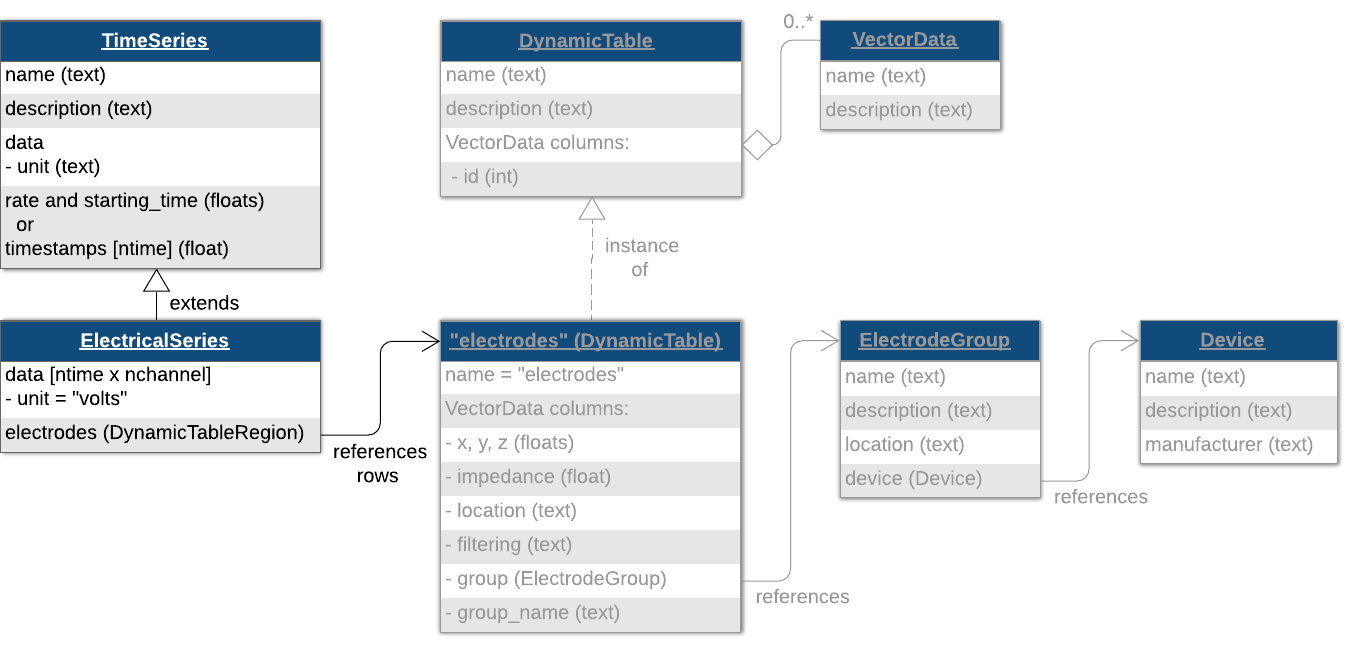

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(12, 3000), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'V');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group. 

nwb.acquisition.set('ElectricalSeries', electrical_series);

NWB has a few main groups for organizing data:

- `acquisition`: Data directly from the acquisition system with minimal processing, including neural and behavioral data. It is recommended that you store and publish data with as little processing as possible.

- `processing`: Data that has been converted, scaled, resampled, or in some other way derived from acquired data. It is not necessary for the corresponding acquired data to be in the acquisition group- some users prefer to separate into two separate NWB files (but in this tutorial we are going to but them in one single file).

- `analysis`: Results of analysis can be placed here to share them packaged with the raw data.

- `stimulus`: sensory presentations or direct neural manipulations of the experiment.

## LFP

Local field potentail (LFP) refers in this case to data that has been downsampled and/or filtered from the original acquisition data and is used to analyze signals in the lower frequency range. Filtered and downsampled LFP data would also be stored in an `ElectricalSeries`. To help data analysis and visualization tools know that this `ElectricalSeries` object represents LFP data, store it inside an `LFP` object, then place the `LFP` object in a `ProcessingModule` named `'ecephys'`. This is analogous to how we stored the `SpatialSeries` object inside of a `Position` object and stored the `Position` object in a `ProcessingModule` named `'behavior'` earlier.

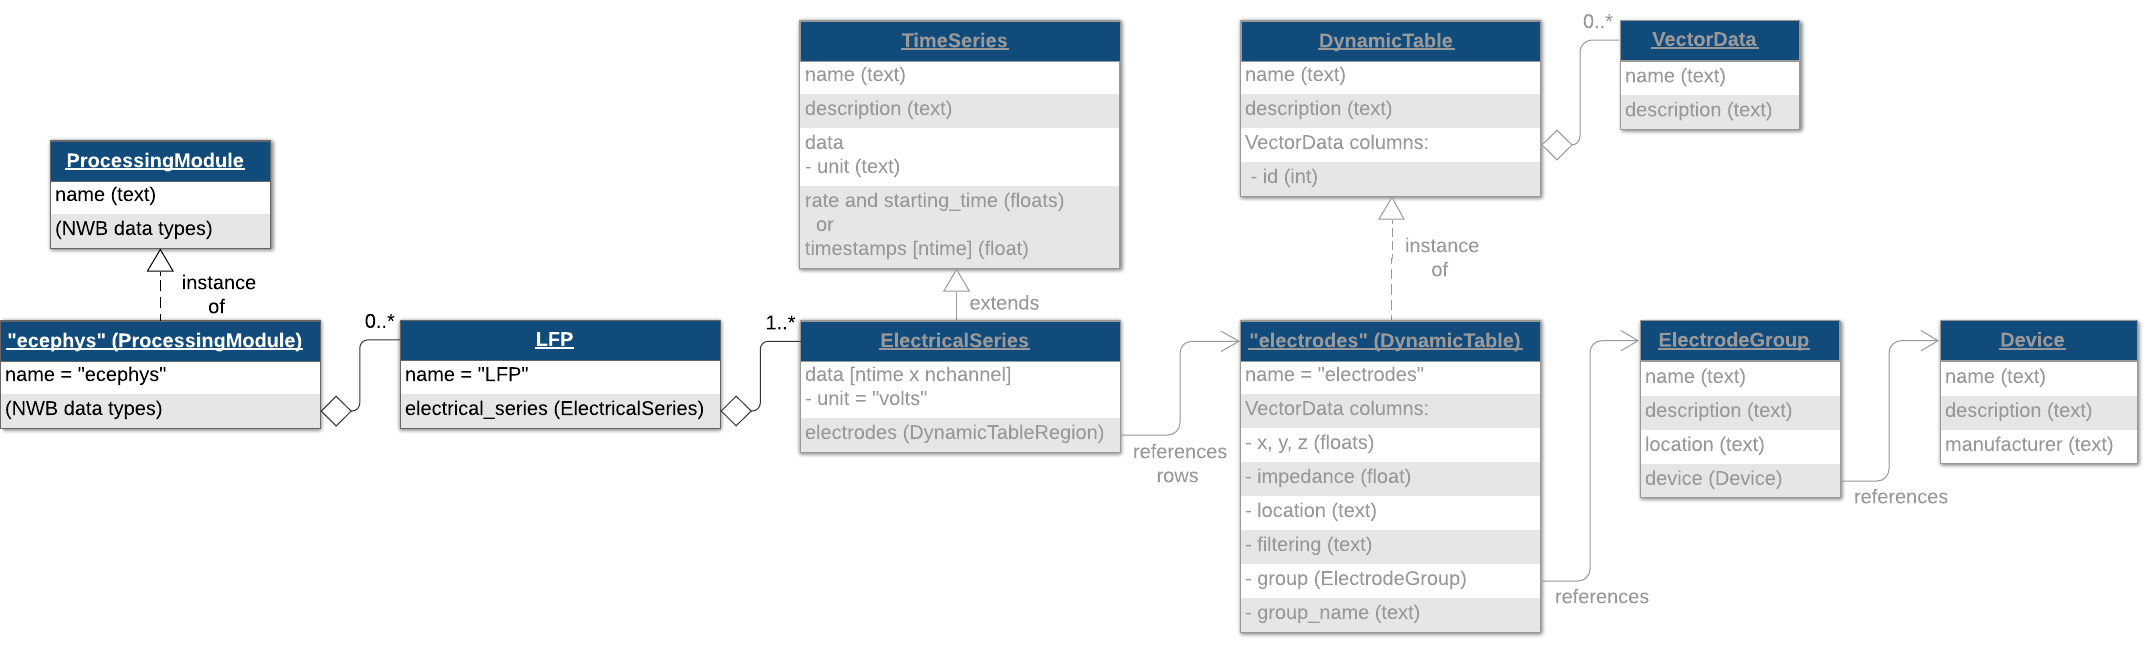

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(12, 100), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'V');

lfp = types.core.LFP('ElectricalSeries', electrical_series);

lfp =   LFP with properties:

    electricalseries: [1×1 types.untyped.Set]



ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

## Spike times

#### Ragged arrays

Spike times are stored in another `DynamicTable` of subtype `Units`. The default `Units` table is at `/units` in the HDF5 file. You can add columns to the `Units` table just like you did for `electrodes` and `trials`. Here, we generate some random spike data and populate the table. 

num_cells = 10;
firing_rate = 20;
spikes = cell(1, num_cells);
for ishank = 1:num_cells
    spikes{ishank} = [];
    for iunit = 1:poissrnd(20)
        spikes{ishank}(end+1) = cumsum(exprnd(1/firing_rate));
    end
end
spikes

spikes = 1×10 cell array
    {1×20 double}    {1×19 double}    {1×23 double}    {1×22 double}    {1×17 double}    {1×18 double}    {1×21 double}    {1×24 double}    {1×19 double}    {1×25 double}


Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the units `DynamicTable`. These indexed columns have two components, the vector data object that holds the data and the vector index object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects.

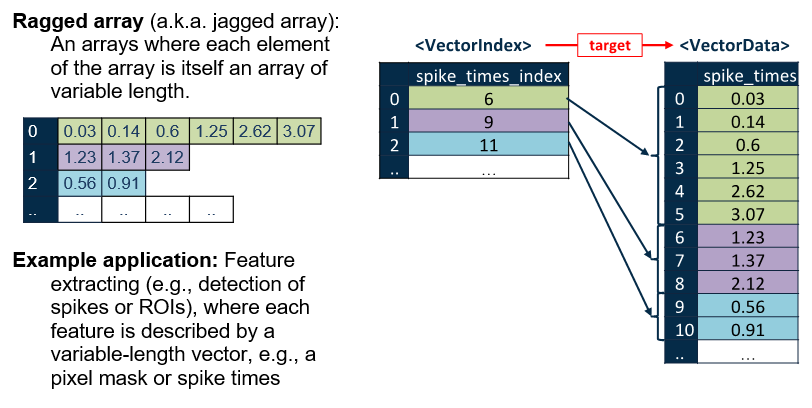

[spike_times_vector, spike_times_index] = util.create_indexed_column( ...
    spikes, '/units/spike_times');

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'id', types.hdmf_common.ElementIdentifiers( ...
    'data', int64(0:length(spikes) - 1)), ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index);

## Write the file

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. Index this array with the `load` method. 

`load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb')

nwb2 =   NwbFile with properties:

                                nwb_version: '2.2.5'
                                acquisition: [1×1 types.untyped.Set]
                                   analysis: [0×1 types.untyped.Set]
                           file_create_date: [1×1 types.untyped.DataStub]
                                    general: [0×1 types.untyped.Set]
                    general_data_collection: []
                            general_devices: [1×1 types.untyped.Set]
             general_experiment_description: []
                       general_experimenter: [1×1 types.untyped.DataStub]
                general_extracellular_ephys: [4×1 types.untyped.Set]
     general_extracellular_ephys_electrodes: [1×1 types.hdmf_common.DynamicTable]
                        general_institution: 'University of My Institution'
                general_intracellular_ephys: [0×1 types.untyped.Set]
      general_intracellular_ephy

nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing data regions

It is often preferable to read only a portion of the data. To do this, use the `load` method with input arguments. The following takes elements 1:5 and 1:10 from the data we have written.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load([1,1],[5,10])

ans =    -0.1431    1.0357    0.4259   -0.3258   -0.9280   -0.1299    0.1533    0.1628   -0.9335   -0.1929
   -0.6446    1.2811   -1.0398    1.6077   -1.8097    0.2220   -0.2633    0.5219   -0.3865   -0.8691
    1.2887    0.9058   -0.8509    3.3896    1.4766   -0.0446    0.8113    1.9684   -0.7423    0.8025
   -0.6818   -2.5232    0.6774    0.7401   -2.5035    0.0803    1.2113   -0.3003    1.4458    0.2272
   -2.3398   -0.5456    1.2638   -0.7668    0.2020    0.4087    1.6756   -0.7327   -0.7699   -1.0460



% You can use the utility function |util.read_indexed_column| to read the
% spike times of a specific unit.
util.read_indexed_column( ...
    nwb.units.spike_times_index, nwb.units.spike_times, 1)

ans =     0.0171
    0.0784
    0.0441
    0.0369
    0.0021
    0.0182
    0.1655
    0.0660
    0.0067
    0.0161


# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)